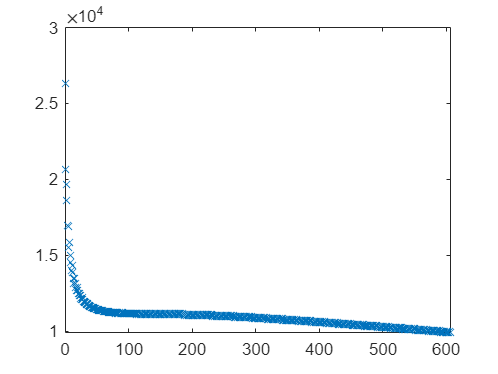

clear;close;clc;
% lines = readlines("tri_3_lean.txt");
% lines = lines(lines.startsWith("0"));
% lines = lines(~lines.contains("SUBCASE 1 "));
% lines(1);
% 
% id = arrayfun(@(line) getID(line),lines); % elem id
% stress = arrayfun(@(line) getStress(line),lines); % max pincipal stress

[id3, stress3] = IdAndStressFromData(readlines("tri_3_lean.txt"));
plot(id3-id3(1),stress3,'x')

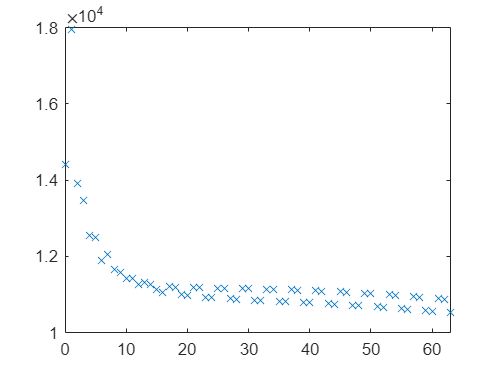


[id2, stress2] = IdAndStressFromData(readlines("tri_2_lean.txt"));
plot(id2-id2(1),stress2,'x')

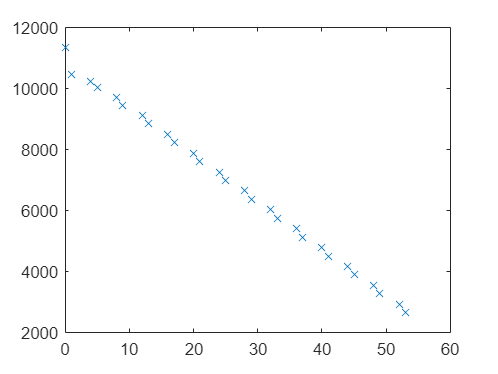


[id1, stress1] = IdAndStressFromData(readlines("tri_1_lean.txt"));
for i = 1:length(id1)
    if(mod(i,4)==1 ||mod(i,4)==0)
        id1(i) = nan;
        stress1(i) = nan;
    end
end

id1 = rmmissing(id1);
stress1 = rmmissing(stress1);
plot(id1-id1(1),stress1,'x')

id1 = id1(1:10)

id1 =    362
   363
   366
   367
   370
   371
   374
   375
   378
   379


stress1 = stress1(1:10)

stress1 = 1.0e+04 *

    1.1360
    1.0472
    1.0218
    1.0018
    0.9715
    0.9457
    0.9118
    0.8845
    0.8501
    0.8226


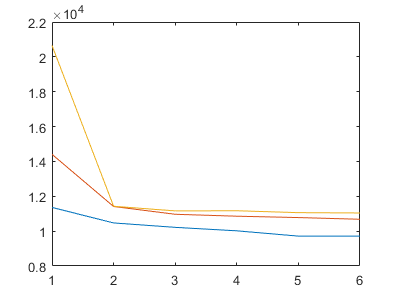


stresses1 = [stress1(1),stress1(2),stress1(3),stress1(4),stress1(5),stress1(5)];
stresses2 = [stress2(1),stress2(11),stress2(21),stress2(32),stress2(41),stress2(52)];
stresses3 = [stress3(1),stress3(51),stress3(100),stress3(151),stress3(201),stress3(251)];
stresses = [stresses1;stresses2;stresses3]';
plot(stresses)

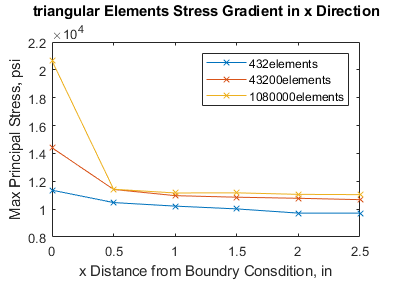


dist = [0:5]*.5;


figure;
plot(dist,stresses,'x-');
legend 432elements 43200elements 1080000elements; hold on;
ylabel('Max Principal Stress, psi');
xlabel({'x Distance from Boundry Consdition, in',''});
title({'triangular Elements Stress Gradient in x Direction',''});

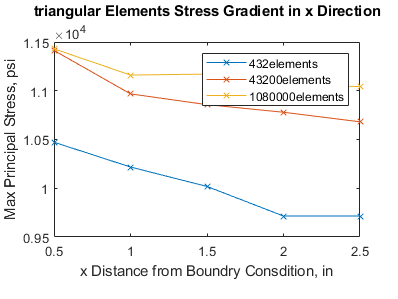


figure;
plot(dist(2:6),stresses(2:6,:),"x-")
legend 432elements 43200elements 1080000elements;
ylabel('Max Principal Stress, psi');
xlabel({'x Distance from Boundry Consdition, in',''});
title({'triangular Elements Stress Gradient in x Direction',''});


stressFit1 = fit(dist(2:5)',stresses(2:5,1),"poly1")

stressFit1 =      Linear model Poly1:
     stressFit1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -494.2  (-611.6, -376.8)
       p2 =   1.072e+04  (1.056e+04, 1.088e+04)

stressFit2 = fit(dist(3:6)',stresses(3:6,2),"poly1")

stressFit2 =      Linear model Poly1:
     stressFit2(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -187.3  (-223.4, -151.3)
       p2 =   1.115e+04  (1.108e+04, 1.122e+04)

stressFit3 = fit(dist(3:6)',stresses(3:6,3),"poly1")

stressFit3 =      Linear model Poly1:
     stressFit3(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -92.74  (-226.7, 41.25)
       p2 =   1.127e+04  (1.102e+04, 1.152e+04)

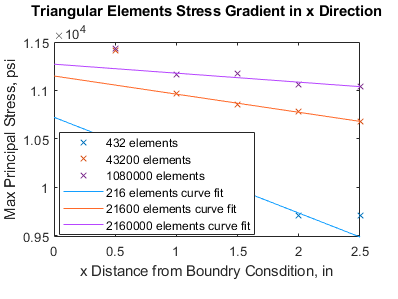


stressFitPoints = zeros(size(stresses));
for i = 1:size(stresses,1)
    stressFitPoints(i,1) = stressFit1(dist(i));
    stressFitPoints(i,2) = stressFit2(dist(i));
    stressFitPoints(i,3) = stressFit3(dist(i));
end
HW_11_Tri_GradientPlot2(dist(2:6),stresses(2:6,:),dist,stressFitPoints)


meshSeedSize = [.5,.05,.01];
elements = (18./meshSeedSize) .* (3./meshSeedSize);
nodes = (18./meshSeedSize+1) .* (3./meshSeedSize+1);
constrainedNodes = 3./meshSeedSize;
degFreePerNode = 3;
degFree = (nodes-constrainedNodes)*degFreePerNode

degFree =          759       65883     1625403



myfittype = fittype('b*(x-a)/(x-c)',...
    'dependent',{'y'},'independent',{'x'},...
    'coefficients',{'a','b','c'})

myfittype =      General model:
     myfittype(a,b,c,x) = b*(x-a)/(x-c)

myfit = fit(degFree',stressFitPoints(1,:)',myfittype)

myfit =      General model:
     myfit(x) = b*(x-a)/(x-c)
     Coefficients:
       a =  -1.791e+04
       b =   1.128e+04
       c =  -1.888e+04

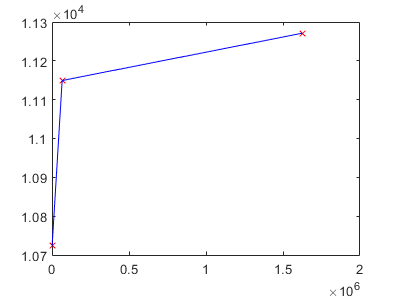


figure;
plot(degFree,stressFitPoints(1,:),'xr');hold on;
plot(degFree,stressFitPoints(1,:),'-b');

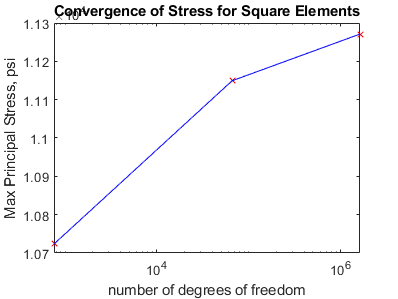

%plot(myfit,'.g')
figure;

semilogx(degFree,stressFitPoints(1,:),'xr'); hold on;
semilogx(degFree,stressFitPoints(1,:),'-b');
%plot(myfit,'.g')
ylabel("Max Principal Stress, psi");
xlabel("number of degrees of freedom");
title("Convergence of Stress for Triangular Elements")


stressFitPoints(1,:)

ans = 1.0e+04 *

    1.0724    1.1149    1.1271


function [id,stress] = IdAndStressFromData(lines)
    lines = lines(lines.startsWith("0"));
    lines = lines(~lines.contains("SUBCASE 1 "));
    id = arrayfun(@(line) getID(line),lines); % elem id
    stress = arrayfun(@(line) getStress(line),lines); % max pincipal stress
end

function [elementID, Stress] = getIDAndStress(line)
    dataLine = str2num(line);
    elementID = dataLine(2);
    Stress= dataLine(8); %output [elementID, Stress]
end

function elementID = getID(line)
    dataLine = str2num(line);
    elementID = dataLine(2);
end

function stress = getStress(line)
    dataLine = str2num(line);
    stress= dataLine(8);
end